sm = SessManager;
d = sm.cons_usable(69);

Total trials: 371	Throwing away 0	keeping 371


load(d.source_path);
X = tracesEvents.rawTraces;
E = hyperdetect(X, 'z_val', 3, 'OutType', 'onset', 'Progress', true);

Detecting 497 cells
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
200
400
Done


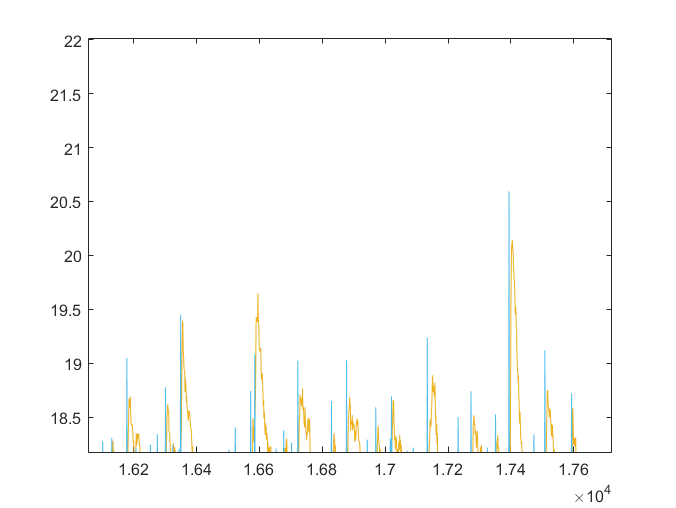

figure;

n_sel = 10;
idx = randperm(size(X,2), n_sel);
gaps = (0:n_sel - 1)*2;
X_sub = X(:, idx) + gaps;
E_sub = E(:, idx) + gaps;

plot(X_sub); hold on
plot(E_sub);